# 测试（直接法）

clc
clear
close all
addpath("src\");

## C-W交会

tf = 2000.; % s
x0 = [2200., 8000., 1000., 0., 0., 0.]';  % km, km/s
xf = zeros(6, 1);
p.n = 0.00111; % rad/s
p.tspan = 1; % s
p.f = 0.01; % N/kg; m/s^2

### 双脉冲

[dv, dv0, ~] = Cw2Impulse(p.n, x0, tf, xf)

dv =     8.0691    5.0668    3.0023


dv0 =     1.4451
   -4.7827
    0.8424


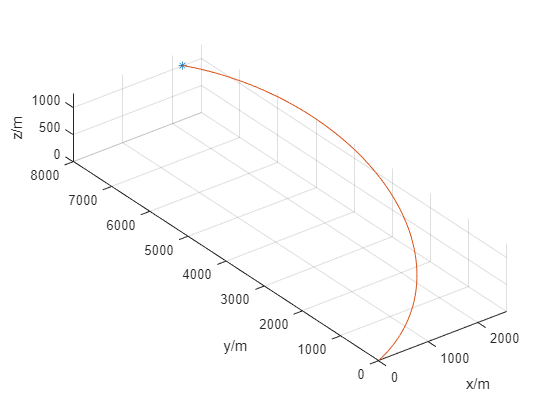

r = x0(1 : 3);
v = x0(4 : 6) + dv0;
[t, x] = ode45(@(t, x) CwEq(t, x, zeros(3, 1), p), 0 : p.tspan : tf, [r; v]);
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

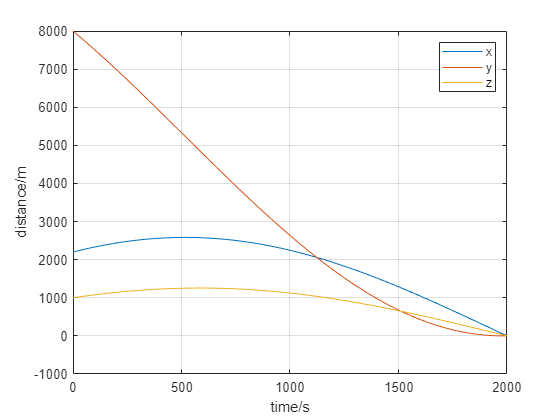

figure
plot(t, x(:, 1 : 3))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')

### 多脉冲转连续推力

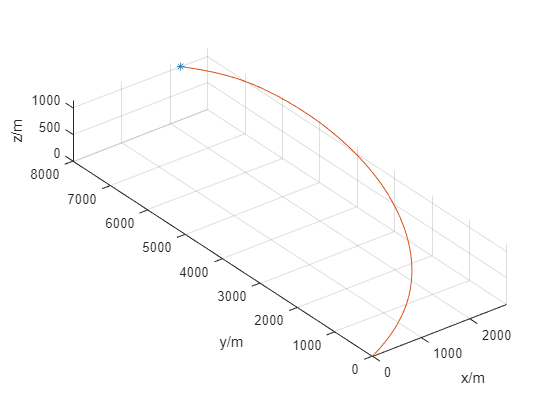

dt = 200;
t1 = 0;
t2 = tf;
x1 = x0;
x2 = xf;
s0 = [];
sf = [];
for i = 1 : tf / dt / 2
    [~, dv0, dvf] = Cw2Impulse(p.n, x1, t2(end) - t1(end), x2);
    u0 = dv0 / dt;
    uf = dvf / dt;
    [t1, s1] = ode45(@(t, x) CwEq(t, x, u0, p), t1(end) + (0 : p.tspan : dt), x1);
%     plot(t1, s1(:, 1), 'b', t1, s1(:, 2), 'r', t1, s1(:, 3), 'y')
    [t2, s2] = ode45(@(t, x) CwEq(t, x, uf, p), t2(end) - (0 : p.tspan : dt), x2);
%     plot(t2, s2(:, 1), 'b', t2, s2(:, 2), 'r', t2, s2(:, 3), 'y')
    x1 = s1(end, :)';
    x2 = s2(end, :)';
    s0 = [s0(1 : end - 1, :); t1, s1, [u0', norm(u0)] .* ones(length(t1), 1)];
    sf = [sf(1 : end - 1, :); t2, s2, [uf', norm(uf)] .* ones(length(t2), 1)];
end
s0 = [s0; flip(sf(1 : end - 1, :))];
figure
plot3(s0(1, 2), s0(1, 3), s0(1, 4), '*')
hold on
plot3(s0(:, 2), s0(:, 3), s0(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

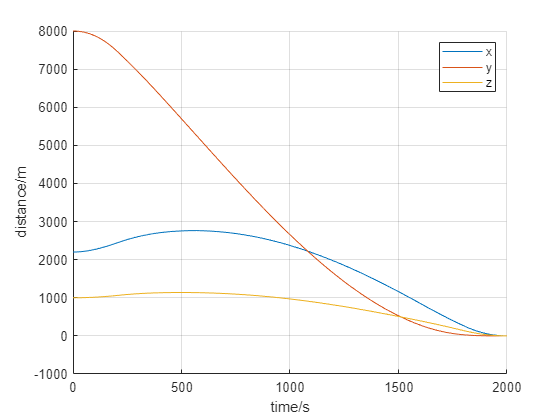

figure
hold on
plot(s0(:, 1), s0(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

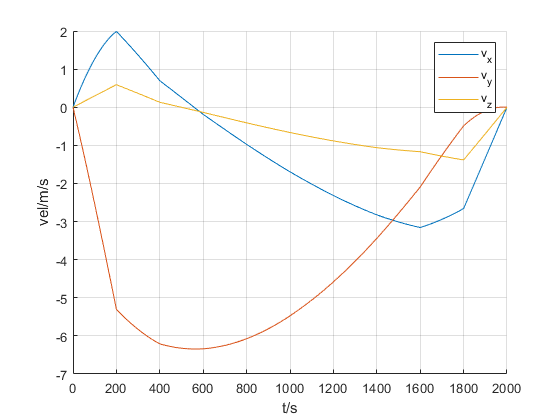

figure
hold on
plot(s0(:, 1), s0(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

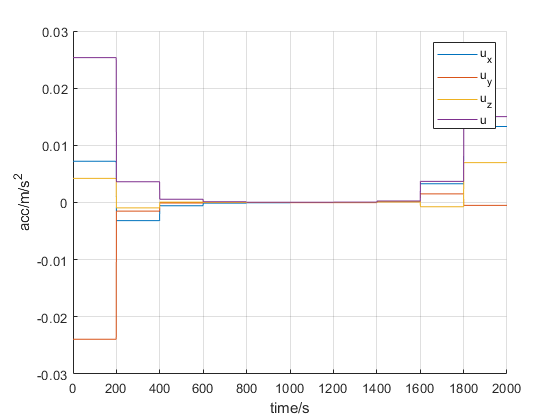

figure
hold on
plot(s0(:, 1), s0(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 能量最优（高斯伪谱）

@CostEnergy: $\int ||{\bf{u}}||^2 \mathrm{d}t$

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      91    4.387380e-03    3.485e+02    1.567e-02
    1     182    1.041546e-02    2.883e+02    6.062e-01    1.633e+00
    2     273    1.046885e-02    2.880e+02    6.092e-01    1.084e-02
    3     364    2.686182e-02    2.444e+02    1.286e+00    2.589e+01
    4     455    2.699043e-02    2.442e+02    1.291e+00    1.315e-01
    5     546    2.648053e-02    2.405e+02    1.290e+00    9.713e+00
    6     637    2.829803e-02    2.280e+02    1.288e+00    3.269e+01
    7     728    2.818889e-02    2.271e+02    1.288e+00    2.505e+00
    8     819    5.634648e-02    1.717e+02    1.970e+00    1.616e+02
    9     910    5.666030e-02    1.714e+02    1.980e+00    8.262e-01
   10    1001    6.890053e-02    1.595e+02    2.393e+00    3.596e+01
   11    

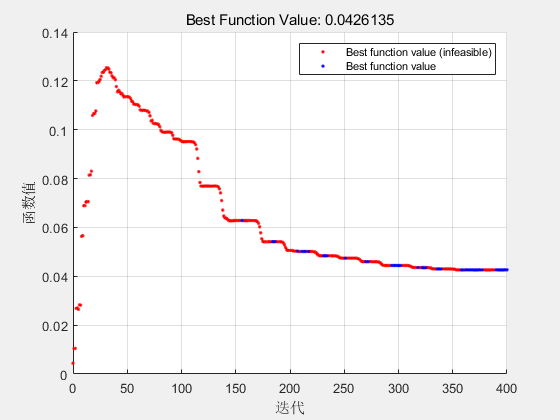


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


lb = [-1000, -1000, -1000, -10, -10, -10, -0.01, -0.01, -0.01];
ub = [3000, 9000, 2000, 10, 10, 10, 0.01, 0.01, 0.01];
[s, x_nlp, fval, exitflag, output, ct] = Gpm(x0, xf, @CostEnergy, @CwEq, s0, lb, ub, 10, p);

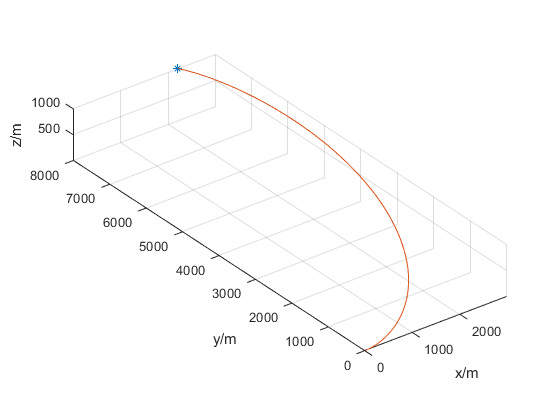

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

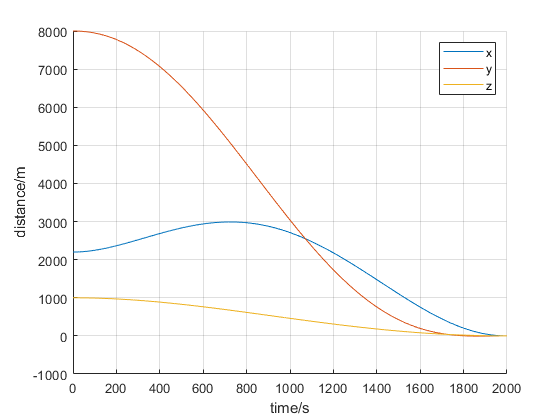

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

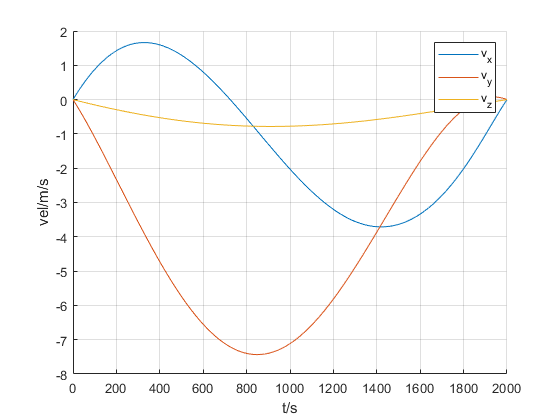

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

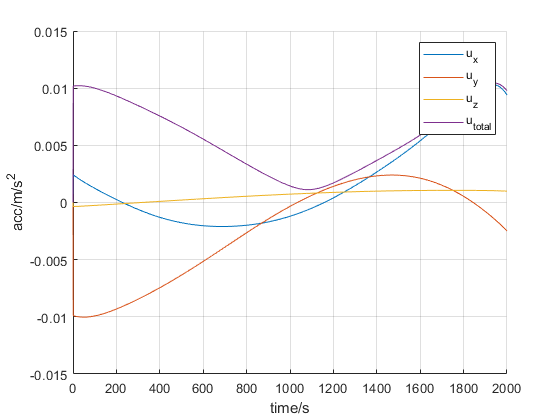

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 燃料最优

@CostFuel: $\int \|{\bf{u}}\| \mathrm{d}t$

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     181    2.148216e+00    6.276e+02    1.000e-01
    1     362    3.163627e+00    5.095e+02    5.294e+01    3.563e-01
    2     543    3.175459e+00    5.083e+02    5.252e+01    2.402e-02
    3     724    3.665130e+00    4.969e+02    7.917e+01    2.053e+00
    4     905    3.606449e+00    4.960e+02    7.706e+01    5.421e-01
    5    1086    7.176814e+00    4.560e+02    1.310e+02    2.628e+01
    6    1267    7.216958e+00    4.557e+02    1.311e+02    2.237e-01
    7    1448    7.335095e+00    4.544e+02    1.312e+02    8.905e-01
    8    1629    5.277663e+00    4.310e+02    1.401e+02    3.337e+01
    9    1810    5.905155e+00    4.204e+02    1.488e+02    1.514e+01
   10    1991    6.497238e+00    4.142e+02    1.425e+02    8.981e+00
   11    

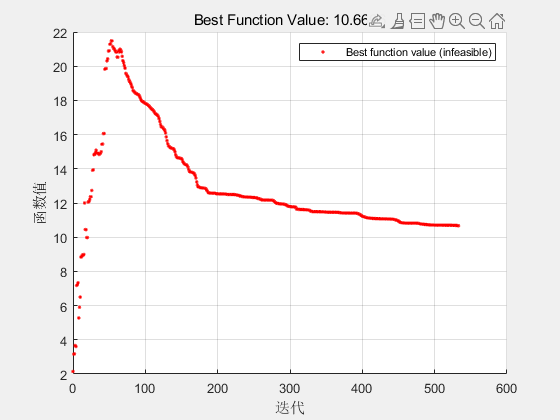


fmincon stopped by the output or plot function.



[s, x_nlp, fval, exitflag, output, ct] = Gpm(x0, xf, @CostFuel, @CwEq, s0, lb, ub, 20, p);

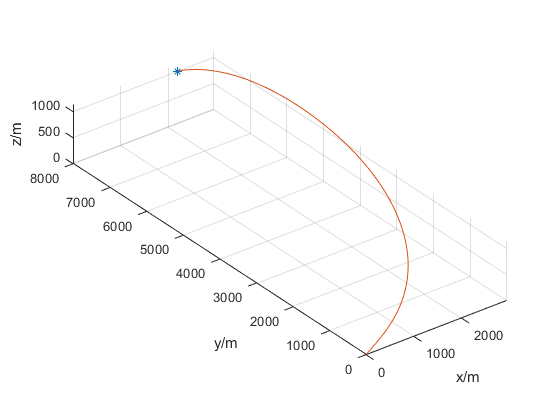

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

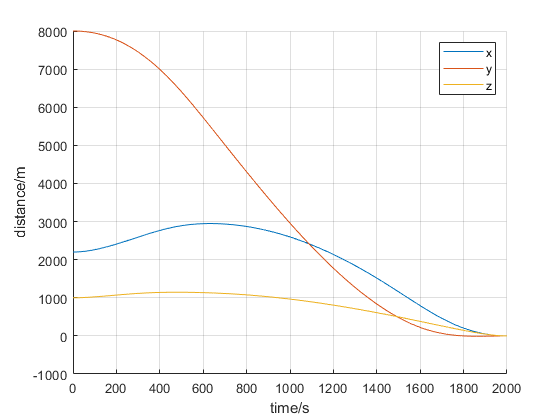

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

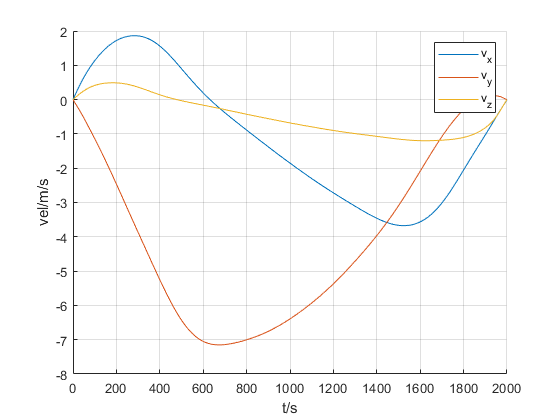

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

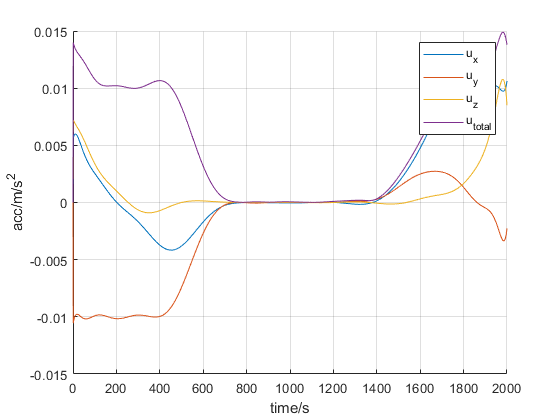

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 时间最优

@CostFuel: $\int 1 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      42    2.000000e+03    2.067e+03    6.008e-02
    1      84    1.211630e+03    1.314e+03    1.372e+02    1.433e+03
    2     127    1.612469e+03    1.160e+03    1.566e+02    6.646e+02
    3     169    1.883387e+03    2.025e+02    2.166e+02    6.649e+02
    4     211    2.011197e+03    3.833e+01    2.356e+02    2.940e+02
    5     253    2.040564e+03    1.077e+01    2.279e+02    3.606e+02
    6     298    2.060394e+03    1.009e+01    2.298e+02    4.613e+01
    7     342    2.095121e+03    8.618e+00    2.342e+02    7.510e+01
    8     386    2.121210e+03    7.075e+00    2.374e+02    5.494e+01
    9     429    2.160408e+03    6.326e+00    2.416e+02    8.167e+01
   10     471    2.199802e+03    5.679e+00    2.448e+02    8.111e+01
   11     513    2.199999e+03    5.639e+00    2.448e+02    4.040e-01
   12     555    2.200000e+03    4.653e+00    2

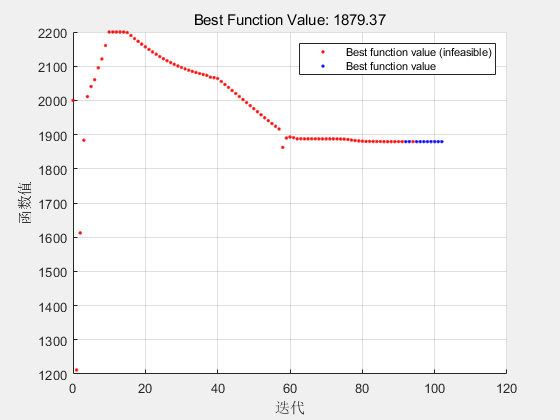


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


s0_ = s0;
for i = 1 : size(s0, 1)
    s0_(i, 8) = atan2(s0(i, 9), s0(i, 8));
    s0_(i, 9) = asin(s0(i, 10));
end
s0_(:, 10 : end) = [];

lb = [-1000, -1000, -1000, -10, -10, -10, -2*pi, -2*pi, 0.1 * tf];
ub = [3000, 9000, 2000, 10, 10, 10, 2*pi, 2*pi, 1.1 * tf];
[s, x_nlp, fval, exitflag, output, ct] = GpmTime(x0, xf, @CostTime, @CwEq, s0, lb, ub, 5, p);

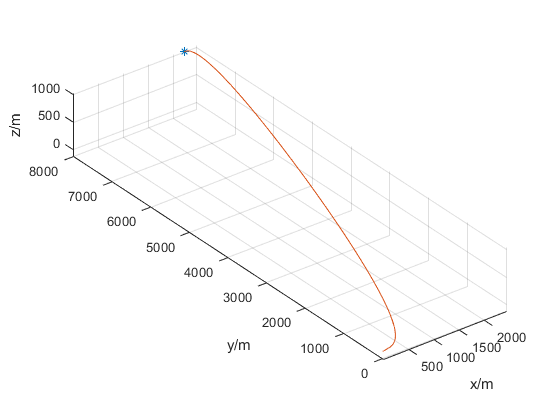

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

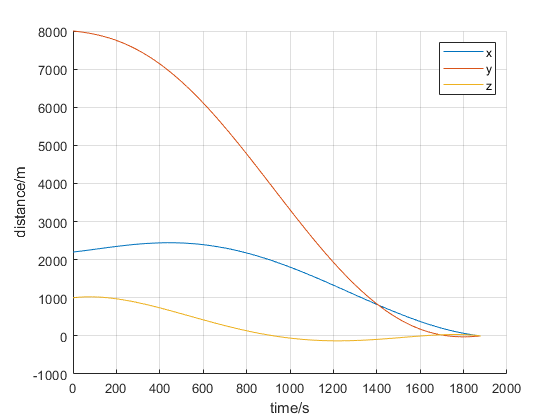

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

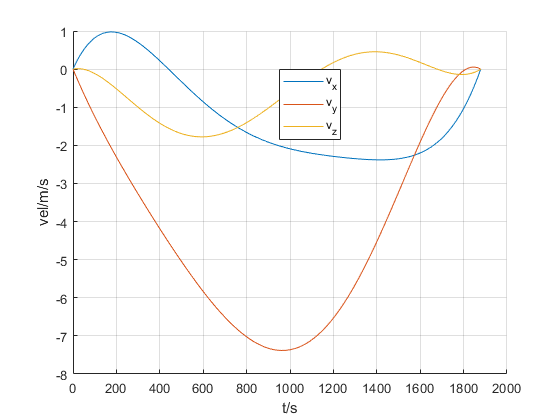

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

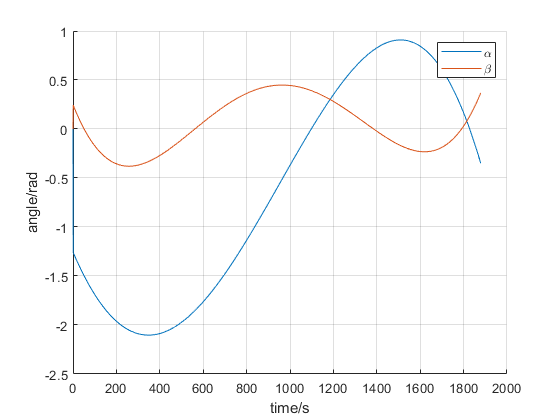

figure
hold on
ang = s(:, 8 : 9);
plot(s(:, 1), ang)
grid on
legend('\alpha', '\beta')
xlabel('time/s')
ylabel('angle/rad')
hold off

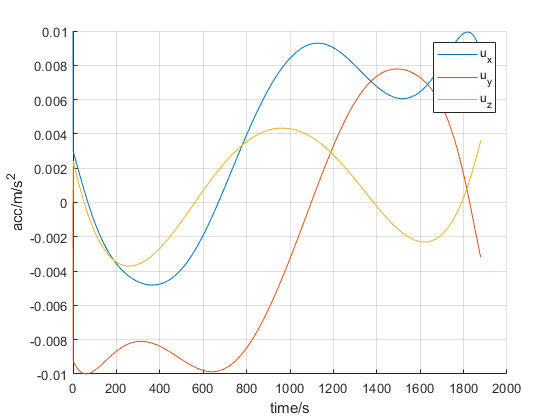

figure
hold on

u = [];
u(:, 1) = p.f * cos(ang(:, 2)) .* cos(ang(:, 1));
u(:, 2) = p.f * cos(ang(:, 2)) .* sin(ang(:, 1));
u(:, 3) = p.f * sin(ang(:, 2));
plot(s(:, 1), u)
grid on
legend('u_x', 'u_y', 'u_z')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off